## Question 1 - Demand Modelling

**This question concerns the modelling of morning commuter flows aggregated at MSOA level in England and Wales, as described in the provided Matlab data file TMMcoursework2024Q1.mat. In this file you will find three data structures: **

**• MSOAdata which provides a code and full name for each of the relevant 7,264 MSOAs, together with centroid coordinates in the form of a northing and easting in the OS grid system. **

**• UTLAdata which provides a code and full name for each of the 174 upper tier local authorities (UTLAs) to which the MSOAs belong. Note the MSOAdata structure provides a lookup index into the UTLA structure, so that you can determine the parent UTLA for each MSOA. **

**• demandData which provides counts for pairs of origin-destination pairs of MSOAs, indexed according to the MSOAdata structure. **

**(The field names should make their purpose clear — but if you are uncertain, post on the discussion forum.) **

% Importing TMMcoursework2024Q1.mat file with required data structures
TMMCourseworkQ1Data = load("TMMcoursework2024Q1.mat");

% Create new variables in the base workspace from those fields.
vars = fieldnames(TMMCourseworkQ1Data);
for i = 1:length(vars)
    assignin('base', vars{i}, TMMCourseworkQ1Data.(vars{i}));
end

### a)  Describe, develop, and demonstrate code to: 

**(i) Build a sparse origin-destination demand matrix and compute its row sums (total origin flows, called Oi in lectures) and column sums (total destination flows, called Dj in lectures).**

Steps:

- Understand the data given and how the structures correspond to each other

- Using MATLABs sparse matrix, create a sparse matrix for all 7264 MSOAs

- Compute the variable Oi by completing a sum of the sparse matrix rows (2)

- Compute the variable Dj by completing a sum of the sparse matrix columns (1)

- Complete a sanity check that the sums of Oi and Dj are equal

- Plot Oi and Dj in histograms

Plot the coordinates of MSOAs to understand locations (more useful for section b).

% Generating the sparse matrix - using demand data origin and destination
% indexes and counts
% Length of sparse matrix set as number of MSOAs
MSOASparseODMatrix = sparse(demandData.MSOAoriginIndex,demandData.MSOAdestinationIndex ...
    ,demandData.count,length(MSOAdata.code),length(MSOAdata.code));

% Computing the row and column sums - Origin total trips from MSOAs (Oi) and
% destination total trip arrivals to MSOAs (Dj)
MSOAOi = sum(MSOASparseODMatrix,2);
MSOADj = sum(MSOASparseODMatrix,1);

% Sanity Check - checking that the number of Origin trips equals number of
% Destination arrivals
sum(MSOADj) == sum(MSOAOi) % 1=True

ans = sparse logical
   (1,1)      1


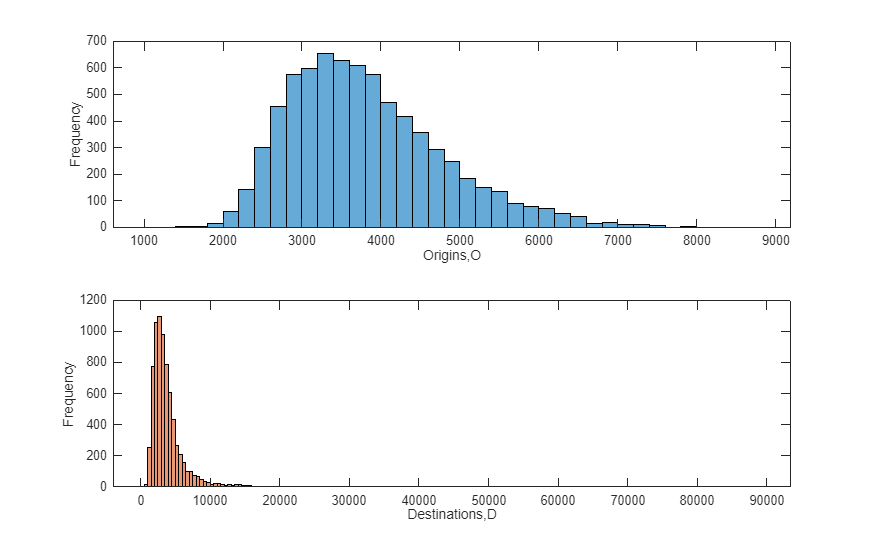

% Setting up figure
figure;

% Plotting the histograms of the Origin frequencies for all MSOA zones
subplot(2,1,1);
histogram(MSOAOi,'FaceColor',[0 0.4470 0.7410])
% Tidying up the graph to look pretty
xlabel("Origins,O")
ylabel("Frequency")

% Plotting the histograms of the Destination frequencies for all MSOA zones
subplot(2,1,2);
histogram(MSOADj,'FaceColor',[0.8500 0.3250 0.0980])
% Tidying up the graph to look pretty
ax = gca;
ax.XAxis.Exponent = 0;
xlabel("Destinations,D")
ylabel("Frequency")

% Specifying figure size
set(gcf,'units','inches','position',[0,0,16,10])

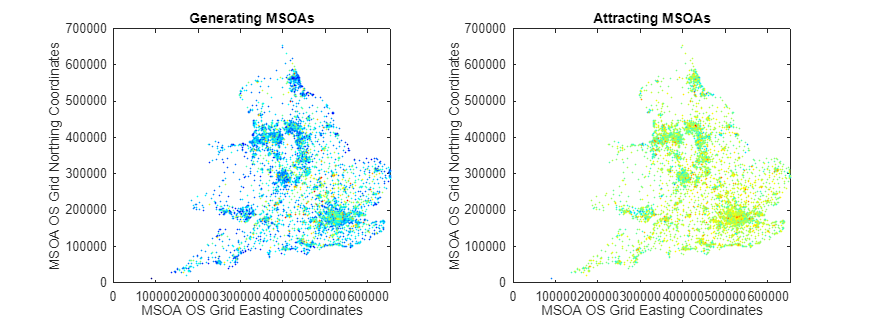


% Calculation of Colour code to see attraction vs generation 
% To see which zones are mainly trip generators and which are mainly trip
% attractors
MSOAOiColourCodes = (MSOAOi - min(MSOAOi)) ./ (max(MSOAOi) - min(MSOAOi)); 
MSOADjColourCodes = log((MSOADj - min(MSOADj)) ./ (max(MSOADj) - min(MSOADj))); 

% Setting up figure
figure;
sz = 2;
tiledlayout(1,2)

nexttile
% Plotting the scatter graph of the MSOA OS Grid coordinates colour coded
% by D/O
scatter(MSOAdata.e, MSOAdata.n, sz,MSOAOiColourCodes,'filled','o');

% Tidying up the graph to look pretty
ax = gca;
ax.YAxis.Exponent = 0;
ax.XAxis.Exponent = 0;
xlabel("MSOA OS Grid Easting Coordinates")
ylabel("MSOA OS Grid Northing Coordinates")
title("Generating MSOAs")
box on

nexttile
scatter(MSOAdata.e, MSOAdata.n, sz,MSOADjColourCodes,'filled','o');

% Tidying up the graph to look pretty
ax = gca;
ax.YAxis.Exponent = 0;
ax.XAxis.Exponent = 0;
xlabel("MSOA OS Grid Easting Coordinates")
ylabel("MSOA OS Grid Northing Coordinates")
title("Attracting MSOAs")
box on

% Setting the colourmap and colourbar
colormap("jet");

set(gcf,'units','inches','position',[0,0,16,6])

**(ii) Compute a matrix of the distances between the centroids of origins and destinations, being careful to state its units**

Steps:

- Understand that MSOA locations have been given in 6 digit OS northing and easting coordinates

- Put the coordinates into a 7264 by 2 matrix

- Calculate the distances between each MSOA using the pdist MATLAB function and use sqaureform to convert from a 1D array to a 7264 by 7264 array

- Divide by 1000 to convert from metres to kilometres

- Plot the distances in a histogram as a sanity check

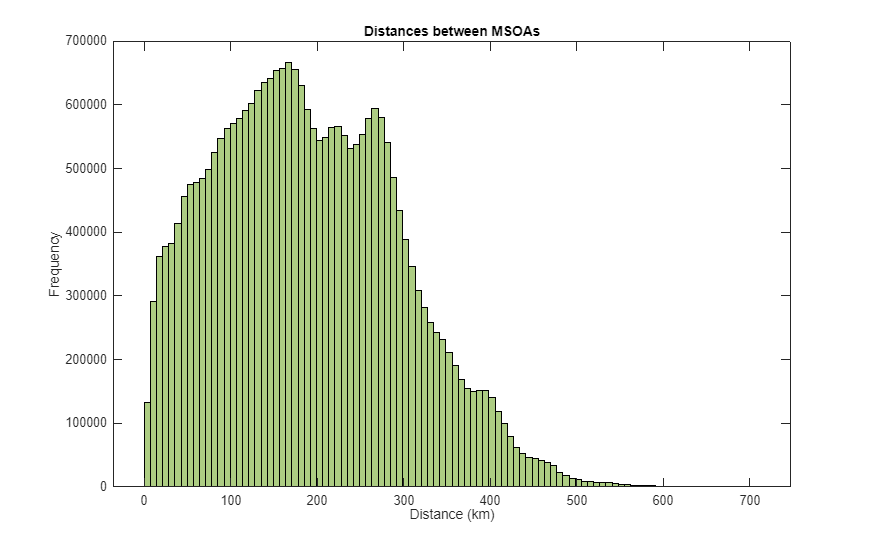

% Putting MSOA locations given in North and East 6 digit OS coodinates into
% a 7264 by 2 matrix
MSOAOSCoordinates = [MSOAdata.e MSOAdata.n];

%Calculating distances between MSOAs in km (hencce dividing by 1000) and then putting into a square
% matrix of 7264 by 7264
MSOADistData = squareform(pdist(MSOAOSCoordinates))./1000;

% Setting up figure
figure;

% Plotting the histograms of the Origin frequencies for all MSOA zones
% Placed into 100 "bins" for ease of view
histogram(unique(MSOADistData),100,'FaceColor',[0.4660 0.6740 0.1880])

% Tidying up the graph to look pretty
xlabel("Distance (km)")
ylabel("Frequency")
title("Distances between MSOAs")
ax = gca;
ax.YAxis.Exponent = 0;
ax.XAxis.Exponent = 0;

% Specifying figure size
set(gcf,'units','inches','position',[0,0,16,10])

**(iii) Investigate best fits to the origin-destination demand data in the form cOiDj/(dij)^α , where dij is the distance data computed in (a)(ii), and c and α are constants to be fitted. You may use a combination of graphical and analytical techniques and full marks will be reserved for scripts which explain methods, discuss results and provide other insightful comment. **

Steps:

- Obtain all non-zero elements from the sparse OD matrix, making sure to record the row and column indices

- Use these indices to obtain the corresponding distances making sure to set any 0 values to NaN

- Setup various Tij matrices with six scenarios explored: c=1 α=1, c=2 α=1, c=3 α=1, c=1 α=2, c=1 α=3, c=1 α=4

- Precalculate OiDj

- Apply logs to the sparse OD matrix non-zero values to get empirical data

- Calculate the relevant Tij values using the distances relevant distances Oi and Dj values specified by the non-zero sparse OD matrix row and column indices. Apply logs to the whole calulcation.

- Calculate the correlation coefficient and Sorensen index for each Tij scenario using the empirical data calculated.

- Plot and compare, making sure to include R and S values in the title of each plot and resize the figure appropriately

Discussion of results:

- When changing the value of c, there is very little difference due to the impact of computing the log. The same values of R and S are obtained while the plotting of the values changes very little. In short, c would have no real impact on the best fit of the gravity model compared to empirical data

- α on the other hand, has a big impact on the best fit of the gravity model to the empirical data. The values of R and S suggest that the best fit value of α sits between 1 and 2 with the plots obtained also showing this as when α=2, the values obtained by the gravity model are all positive while when α=3 some of the model values are negative. The optimal value of α is when the minimum gravity model value sits at zero. Using the plots below it is thought that the best fit value of α sits around 1.4.

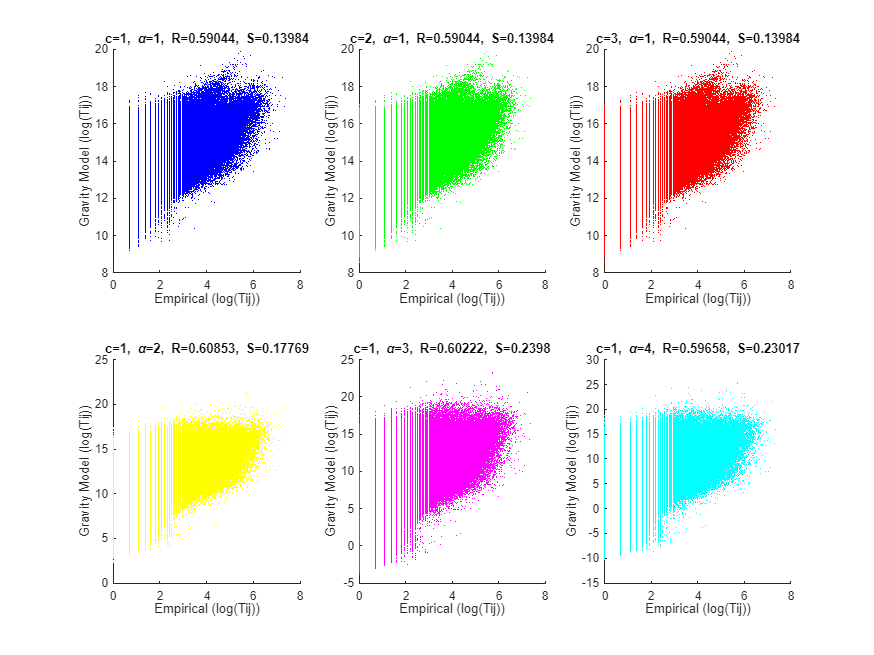

% Obtaining all the non-zero elements from the sparse OD matrix including
% the related row and column indices
[MSOASparseODNonZeroRows,MSOASparseODNonZeroCols,MSOASparseODNonZeroValues] = find(MSOASparseODMatrix);

% Obtaining of the relevant distances between MSOAs form non-zero values in
% the initial sparse OD matrix
DistMatrix = MSOADistData(sub2ind(size(MSOADistData), MSOASparseODNonZeroRows, MSOASparseODNonZeroCols));
% Making sure that no distance values are zero (important later to avoid
% infinite values)
DistMatrix(DistMatrix == 0) = NaN;

% Setting up the various Tij matrices
% c = 1, alpha = 1
OneAndOneMSOATij = zeros(length(MSOASparseODMatrix),length(MSOASparseODMatrix));
% c = 2, alpha = 1
TwoAndOneMSOATij = zeros(length(MSOASparseODMatrix),length(MSOASparseODMatrix));
% c = 3, alpha = 1
ThreeAndOneMSOATij = zeros(length(MSOASparseODMatrix),length(MSOASparseODMatrix));

% c = 1, alpha = 2
OneAndTwoMSOATij = zeros(length(MSOASparseODMatrix),length(MSOASparseODMatrix));
% c = 1, alpha = 3
OneAndThreeMSOATij = zeros(length(MSOASparseODMatrix),length(MSOASparseODMatrix));
% c = 1, alpha = 4
OneAndFourMSOATij = zeros(length(MSOASparseODMatrix),length(MSOASparseODMatrix));

% Precalculation of OiDj for efficiency
OiTimesDj = MSOAOi .* MSOADj;

% Obtaining the empirical data
MSOAEmpirical = log(MSOASparseODNonZeroValues);

% Calculation of Tij for c = 1, alpha = 1 making sure to put value in
% corresponding position to sparse OD matrix and selecting the correct OiDj
% value - logs applied here
OneAndOneMSOATij(sub2ind(size(OneAndOneMSOATij), MSOASparseODNonZeroRows, MSOASparseODNonZeroCols)) = ...
    log(OiTimesDj(sub2ind(size(OneAndOneMSOATij), MSOASparseODNonZeroRows, MSOASparseODNonZeroCols))...
    .* (1 ./ DistMatrix));
% Calculation of Tij for c = 2, alpha = 1 
TwoAndOneMSOATij(sub2ind(size(TwoAndOneMSOATij), MSOASparseODNonZeroRows, MSOASparseODNonZeroCols)) = ...
    log(OiTimesDj(sub2ind(size(TwoAndOneMSOATij), MSOASparseODNonZeroRows, MSOASparseODNonZeroCols))...
    .* (2 ./ DistMatrix));
% Calculation of Tij for c = 3, alpha = 1 
ThreeAndOneMSOATij(sub2ind(size(ThreeAndOneMSOATij), MSOASparseODNonZeroRows, MSOASparseODNonZeroCols)) = ...
    log(OiTimesDj(sub2ind(size(ThreeAndOneMSOATij), MSOASparseODNonZeroRows, MSOASparseODNonZeroCols))...
    .* (3 ./ DistMatrix));

% Calculation of Tij for c = 1, alpha = 2
OneAndTwoMSOATij(sub2ind(size(OneAndTwoMSOATij), MSOASparseODNonZeroRows, MSOASparseODNonZeroCols)) = ...
    log(OiTimesDj(sub2ind(size(OneAndTwoMSOATij), MSOASparseODNonZeroRows, MSOASparseODNonZeroCols))...
    .* (1 ./ DistMatrix.^2));
% Calculation of Tij for c = 1, alpha = 3
OneAndThreeMSOATij(sub2ind(size(OneAndThreeMSOATij), MSOASparseODNonZeroRows, MSOASparseODNonZeroCols)) = ...
    log(OiTimesDj(sub2ind(size(OneAndThreeMSOATij), MSOASparseODNonZeroRows, MSOASparseODNonZeroCols))...
    .* (1 ./ DistMatrix.^3));
% Calculation of Tij for c = 1, alpha = 4
OneAndFourMSOATij(sub2ind(size(OneAndFourMSOATij), MSOASparseODNonZeroRows, MSOASparseODNonZeroCols)) = ...
    log(OiTimesDj(sub2ind(size(OneAndFourMSOATij), MSOASparseODNonZeroRows, MSOASparseODNonZeroCols))...
    .* (1 ./ DistMatrix.^4));


% Extract non-zero values from the Tij matrices (unsure if strictly necessary but helps to tidy up data)
[~, ~, OneAndOneMSOATijNonZeroValues] = find(OneAndOneMSOATij);
[~, ~, TwoAndOneMSOATijNonZeroValues] = find(OneAndOneMSOATij);
[~, ~, ThreeAndOneMSOATijNonZeroValues] = find(OneAndOneMSOATij);

[~, ~, OneAndTwoMSOATijNonZeroValues] = find(OneAndTwoMSOATij);
[~, ~, OneAndThreeMSOATijNonZeroValues] = find(OneAndThreeMSOATij);
[~, ~, OneAndFourMSOATijNonZeroValues] = find(OneAndFourMSOATij);

% Computing the value of correlation coefficient between the Tij values
% from the gravity model and the emipirical data

% Calculation of R for c = 1, alpha = 1 
OneAndOneR = corrcoef(OneAndOneMSOATijNonZeroValues,MSOAEmpirical,'Rows','complete');
% Calculation of R for c = 2, alpha = 1 
TwoAndOneR = corrcoef(TwoAndOneMSOATijNonZeroValues,MSOAEmpirical,'Rows','complete');
% Calculation of R for c = 3, alpha = 1 
ThreeAndOneR = corrcoef(ThreeAndOneMSOATijNonZeroValues,MSOAEmpirical,'Rows','complete');

% Calculation of R for c = 1, alpha = 2
OneAndTwoR = corrcoef(OneAndTwoMSOATijNonZeroValues,MSOAEmpirical,'Rows','complete');
% Calculation of R for c = 1, alpha = 3
OneAndThreeR = corrcoef(OneAndThreeMSOATijNonZeroValues,MSOAEmpirical,'Rows','complete');
% Calculation of R for c = 1, alpha = 4
OneAndFourR = corrcoef(OneAndFourMSOATijNonZeroValues,MSOAEmpirical,'Rows','complete');

% Computing the value of Sorensen coefficient between the Tij values
% from the gravity model and the emipirical data

% Calculation of S for c = 1, alpha = 1 
OneAndOneSorensen = 2*sum(min(OneAndOneMSOATijNonZeroValues,MSOAEmpirical,'omitnan'),'omitnan')...
/(sum(OneAndOneMSOATijNonZeroValues,'omitnan') + sum(MSOAEmpirical,'omitnan'));
% Calculation of S for c = 2, alpha = 1 
TwoAndOneSorensen = 2*sum(min(TwoAndOneMSOATijNonZeroValues,MSOAEmpirical,'omitnan'),'omitnan')...
/(sum(TwoAndOneMSOATijNonZeroValues,'omitnan') + sum(MSOAEmpirical,'omitnan'));
% Calculation of S for c = 3, alpha = 1 
ThreeAndOneSorensen = 2*sum(min(ThreeAndOneMSOATijNonZeroValues,MSOAEmpirical,'omitnan'),'omitnan')...
/(sum(ThreeAndOneMSOATijNonZeroValues,'omitnan') + sum(MSOAEmpirical,'omitnan'));

% Calculation of S for c = 1, alpha = 2
OneAndTwoSorensen = 2*sum(min(OneAndTwoMSOATijNonZeroValues,MSOAEmpirical,'omitnan'),'omitnan')...
/(sum(OneAndTwoMSOATijNonZeroValues,'omitnan') + sum(MSOAEmpirical,'omitnan'));
% Calculation of S for c = 1, alpha = 3
OneAndThreeSorensen = 2*sum(min(OneAndThreeMSOATijNonZeroValues,MSOAEmpirical,'omitnan'),'omitnan')...
/(sum(OneAndThreeMSOATijNonZeroValues,'omitnan') + sum(MSOAEmpirical,'omitnan'));
% Calculation of S for c = 1, alpha = 4
OneAndFourSorensen = 2*sum(min(OneAndFourMSOATijNonZeroValues,MSOAEmpirical,'omitnan'),'omitnan')...
/(sum(OneAndFourMSOATijNonZeroValues,'omitnan') + sum(MSOAEmpirical,'omitnan'));

% Setting size of points
sz = 1;

% Setting up figure
figure;

% Plotting of Tij for c = 1, alpha = 1 
subplot(2,3,1)
scatter(MSOAEmpirical,OneAndOneMSOATijNonZeroValues,sz,'filled','o','MarkerFaceColor','blue')
xlabel('Empirical (log(Tij))'); 
ylabel('Gravity Model (log(Tij))');
% Relevant R and S value in title
title("c=1, \alpha=1, R=" + OneAndOneR(1,2) + ", S=" + OneAndOneSorensen)

% Plotting of Tij for c = 2, alpha = 1 
subplot(2,3,2)
scatter(MSOAEmpirical,TwoAndOneMSOATijNonZeroValues,sz,'filled','o','MarkerFaceColor','green')
xlabel('Empirical (log(Tij))'); 
ylabel('Gravity Model (log(Tij))');
% Relevant R and S value in title
title("c=2, \alpha=1, R=" + TwoAndOneR(1,2) + ", S=" + TwoAndOneSorensen)

% Plotting of Tij for c = 3, alpha = 1 
subplot(2,3,3)
scatter(MSOAEmpirical,ThreeAndOneMSOATijNonZeroValues,sz,'filled','o','MarkerFaceColor','red')
xlabel('Empirical (log(Tij))'); 
ylabel('Gravity Model (log(Tij))');
% Relevant R and S value in title
title("c=3, \alpha=1, R=" + ThreeAndOneR(1,2) + ", S=" + ThreeAndOneSorensen)

% Plotting of Tij for c = 1, alpha = 2 
subplot(2,3,4)
scatter(MSOAEmpirical,OneAndTwoMSOATijNonZeroValues,sz,'filled','o','MarkerFaceColor','yellow')
xlabel('Empirical (log(Tij))'); 
ylabel('Gravity Model (log(Tij))');
% Relevant R and S value in title
title("c=1, \alpha=2, R=" + OneAndTwoR(1,2) + ", S=" + OneAndTwoSorensen)

% Plotting of Tij for c = 1, alpha = 3
subplot(2,3,5)
scatter(MSOAEmpirical,OneAndThreeMSOATijNonZeroValues,sz,'filled','o','MarkerFaceColor','magenta')
xlabel('Empirical (log(Tij))'); 
ylabel('Gravity Model (log(Tij))');
% Relevant R and S value in title
title("c=1, \alpha=3, R=" + OneAndThreeR(1,2) + ", S=" + OneAndThreeSorensen)

% Plotting of Tij for c = 1, alpha = 4
subplot(2,3,6)
scatter(MSOAEmpirical,OneAndFourMSOATijNonZeroValues,sz,'filled','o','MarkerFaceColor','cyan')
xlabel('Empirical (log(Tij))');
ylabel('Gravity Model (log(Tij))');
% Relevant R and S value in title
title("c=1, \alpha=4, R=" + OneAndFourR(1,2) + ", S=" + OneAndFourSorensen)

% Resizing figure
set(gcf,'units','inches','position',[0,0,16,12])

### b)  Describe, develop, and demonstrate code to: 

**(i) Compute the centroid of each UTLA in OS grid coordinates. (You may use a simple average of the MSOA constituent members.) Compute a matrix of distances between UTLA centroids.**

Steps:

- Setup a matrix to store all "useful" UTLA values.

- Extract the UTLA codes and labels from the data structure given.

- Use a loop to calculate the OS cooridnate centroids of UTLAs by taking the mean of the constituent MSOA members' OS coordinates. Place these in a 174 by 2 matrix for distance claculation.

- Calculate the distances between the centroids of UTLAs using pdist and place in 174 by 174 matrix. Divide by 1000 to put in kilometres.

- Plot the calculated UTLA centroid coordinates on a scatter plot and the distances in a histogram.

- The UTLA centroid coordinates are also plotted in (ii) detailing the trip attracting and generating UTLAs.

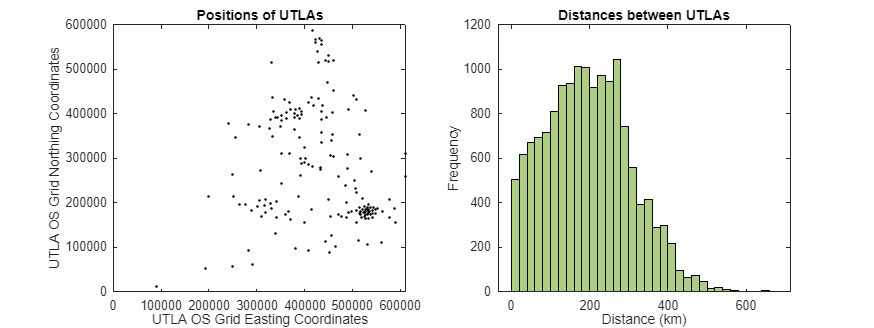

% Extraction of UTLA codes and labels
UTLAUsefulInfo = [];
UTLAUsefulInfo(:,1) = UTLAdata.code;
UTLAUsefulInfo(:,2) = UTLAdata.label;

% Calculating centroids of UTLAs using the average of the MSOA constituent
% members
for i=1:length(UTLAUsefulInfo)
    indexes = find(MSOAdata.UTLAindex == i);
    UTLAUsefulInfo(i,3) = mean(MSOAdata.e(indexes));
    UTLAUsefulInfo(i,4) = mean(MSOAdata.n(indexes));
end

% Putting UTLA locations given in North and East 6 digit OS coodinates into
% a 174 by 2 matrix
UTLAOSCoordinates = [UTLAUsefulInfo(:,3) UTLAUsefulInfo(:,4)];

%Calculating distances between UTLAs in km and then putting into a square
% matrix of 174 by 174
UTLADistData = squareform(pdist(UTLAOSCoordinates))./1000; 

% Setting up figure
figure;

subplot(1,2,1)
sz = 4;
% Plotting the scatter graph of the UTLA OS Grid coordinates colour coded
% by D/O
scatter(UTLAUsefulInfo(:,3), UTLAUsefulInfo(:,4), sz,'filled','o','MarkerFaceColor','black');

% Tidying up the graph to look pretty
ax = gca;
ax.YAxis.Exponent = 0;
ax.XAxis.Exponent = 0;
xlabel("UTLA OS Grid Easting Coordinates")
ylabel("UTLA OS Grid Northing Coordinates")
title("Positions of UTLAs")
box on

subplot(1,2,2)

% Plotting the histograms of the Origin frequencies for all MSOA zones
histogram(unique(UTLADistData),'FaceColor',[0.4660 0.6740 0.1880])

% Tidying up the graph to look pretty
xlabel("Distance (km)")
ylabel("Frequency")
title("Distances between UTLAs")
ax = gca;
ax.YAxis.Exponent = 0;
ax.XAxis.Exponent = 0;

% Specifying figure size
set(gcf,'units','inches','position',[0,0,16,6])

**(ii) Compute the 174 × 174 origin-destination matrix that describes flows at UTLA-UTLA level, and the corresponding row sums (origin flows) and column sums (destination flows).**

Steps:

- Setup the UTLA OD matrix as a 174 by 174 matrix.

- Extracting the origin and destination flows from the constituent MSOA OD matrix and summing these to obtain the total UTLA flows for each origin and destination UTLA.

- Turn the UTLA OD matrix into a sparse matrix for efficiency.

- Compute origin flows using row sum of UTLA OD sparse matrix (2).

- Compute destination flows using column sum of UTLA OD sparse matrix (1).

- Plot a histogram of all the non-zero origin and destination flows for a sanity check.

- The UTLA centroid coordinates are also plotted in and colour coded detailing the trip attracting and generating UTLAs.

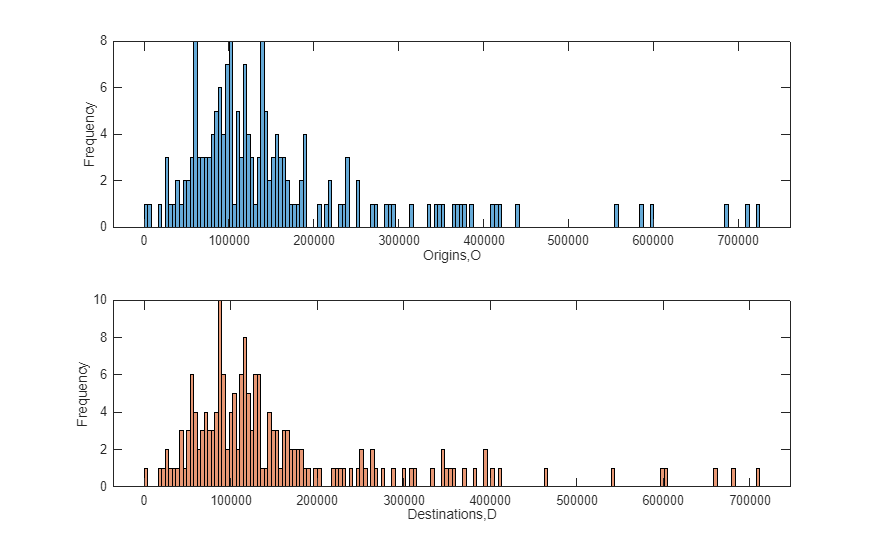

% Setting up UTLA OD Matrix with zeros based on number of individual UTLA
% codes
UTLAODMatrix = zeros(length(UTLAUsefulInfo),length(UTLAUsefulInfo));

% Extracting sums of O and D frequencies using constituent MSOA members 
for i=1:length(UTLAUsefulInfo)
        indexesO = find(MSOAdata.UTLAindex == i);
    for j=1:length(UTLAUsefulInfo)
        indexesD = find(MSOAdata.UTLAindex == j);
        UTLAODMatrix(i,j) = sum(MSOASparseODMatrix(indexesO,indexesD),'all');
    end
end

% Turning OD UTLA matrix into a sparse matrix
UTLASparseODMatrix = sparse(UTLAODMatrix);

% Computing the row and column sums - Origin total trips from UTLAs (Oi) and
% destination total trip arrivals to UTLAs (Dj)
UTLAOi = sum(UTLASparseODMatrix,2);
UTLADj = sum(UTLASparseODMatrix,1);

% Setting up figure for hisograms of orign and destination frequencies
figure;
nBins = length(UTLAOi);
[~,~,OiVals] = find(UTLAOi);
[~,~,DjVals] = find(UTLADj);

% Plotting the histograms of the Origin frequencies for all UTLA zones
subplot(2,1,1);
histogram(OiVals,nBins,'FaceColor',[0 0.4470 0.7410])
% Tidying up the graph to look pretty
ax = gca;
ax.XAxis.Exponent = 0;
xlabel("Origins,O")
ylabel("Frequency")


% Plotting the histograms of the Destination frequencies for all UTLA zones
subplot(2,1,2);
histogram(DjVals,nBins,'FaceColor',[0.8500 0.3250 0.0980])
% Tidying up the graph to look pretty
ax = gca;
ax.XAxis.Exponent = 0;
xlabel("Destinations,D")
ylabel("Frequency")


% Specifying figure size
set(gcf,'units','inches','position',[0,0,16,10])

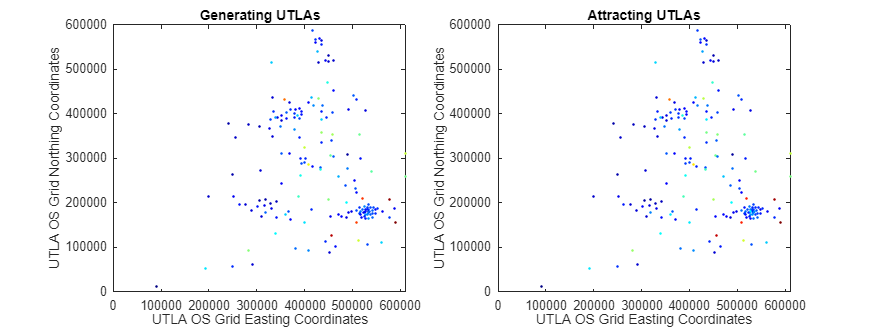


% Calculation of Colour code to see attraction vs generation 
% To see which zones are mainly trip generators and which are mainly trip
% attractors

UTLAOiColourCodes = (UTLAOi - min(UTLAOi)) ./ (max(UTLAOi) - min(UTLAOi)); 
UTLADjColourCodes = (UTLADj - min(UTLADj)) ./ (max(UTLADj) - min(UTLADj)); 

% Setting up figure
figure;

subplot(1,2,1)
sz = 4;
% Plotting the scatter graph of the UTLA OS Grid coordinates colour coded
scatter(UTLAUsefulInfo(:,3), UTLAUsefulInfo(:,4), sz,UTLAOiColourCodes,'filled','o');

% Setting the colourmap and colourbar
colormap("jet");

% Tidying up the graph to look pretty
ax = gca;
ax.YAxis.Exponent = 0;
ax.XAxis.Exponent = 0;
xlabel("UTLA OS Grid Easting Coordinates")
ylabel("UTLA OS Grid Northing Coordinates")
title("Generating UTLAs")
box on

subplot(1,2,2)
sz = 4;
% Plotting the scatter graph of the UTLA OS Grid coordinates colour coded
scatter(UTLAUsefulInfo(:,3), UTLAUsefulInfo(:,4), sz,UTLADjColourCodes,'filled','o');

% Setting the colourmap and colourbar
colormap("jet");

% Tidying up the graph to look pretty
ax = gca;
ax.YAxis.Exponent = 0;
ax.XAxis.Exponent = 0;
xlabel("UTLA OS Grid Easting Coordinates")
ylabel("UTLA OS Grid Northing Coordinates")
title("Attracting UTLAs")
box on

% Specifying figure size
set(gcf,'units','inches','position',[0,0,16,6])

Plots above are not quite identical - look around the london area to see some differing colours

### (c) Using your results from part (b), compute, compare, and comment on the performance of the origin-constrained and destination-constrained gravity models on UTLA-UTLA demand data.

Steps:

- First, setting all non-zero values of distance and flow to zero in the distance and OD matrices.

- Pre-calculate 1/dij^2 using the distance matrix. Non-zero values mean no inifinities obtained.

- Calculate the initial Tij with no normalisation coefficients. Calculating the row and column sums (2 and 1) of this Tij matrix to obtain the origin and destination flows.

- Calculation the normalisation values using the empirical Oi and Dj values and dividing them by those obtained by the initial Tij Oi and Dj values.

- Computing the Origin-Constrained UTLA Tij using the Oi Normalisation values. 

- Computing the Destination-Constrained UTLA Tij using the Dj Normalisation values. 

- Sanity check using MSOA and UTLA empirical values making sure the total number of journeys is all equal.

- Plotting the origin-constrained, empirical and destination-constrained flows as three heatmaps making sure to add the relevant title to each one.

-  Resizing the figure and showing the colourbar.

Comments on performance:

- Both the origin-constrained and destination-contrained gravity models perform similarly and poorly when compared to the empirical data.

- However, both contrained models show a similar trend compared to the empirical data of the most trips being within UTLAs and neighboruing UTLAs. This is shown by the diagonal lines seen in all the heat maps from the bottom left to top right of the plot.

- Both the orign and destination constrained models appear to show more trips in the top UTLAs with both more origins and destinations present for a few seemingly random UTLAs.

- Specifically there is a lot of journeys around UTLA zone 130. This makes sense as it is the main London UTLAs e.g. Westminster, Richmond etc. which, as the data given is about commutes, makes sense why it shows up so strongly as these are heavy commuter workplaces relative to other parts of the country. This is an indication of the (somewhat) validation of the models.

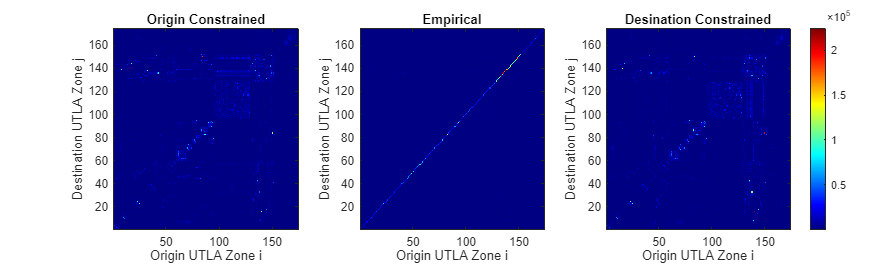

% Setting all non-zero values of distance to NaN
UTLADistData(UTLADistData == 0) = NaN;
% Pre-calulcation of 1/dij^2 for efficiency
fdij = 1./(UTLADistData.^2);

% Setting all non-zero values in the UTLA sparse OD matrix to NaN
UTLASparseODMatrix(UTLASparseODMatrix == 0) = NaN;

% Obtaining empirical data
UTLAEmpirical = UTLASparseODMatrix;

% Calculation of initial Tij
UTLATij = UTLAOi.*UTLADj.*fdij;

% Row and column sums for Oi and Dj respecitvely
UTLATijOi = sum(UTLATij,2,"omitnan");
UTLATijDj = sum(UTLATij,1,"omitnan");

% Normalisation constants for each row and column in the origin and
% destination constrained gravity model cases
OiNormalisation = UTLAOi./UTLATijOi;
DjNormalisation = UTLADj./UTLATijDj;

% Calculation using the normalisation constants for each row of the
% origin-constrained gravity model
OriginConstrainedUTLATij = (OiNormalisation.*UTLAOi).*UTLADj.*fdij;

% Calculation using the normalisation constants for each column of the
% destination-constrained gravity model
DestinationConstrainedUTLATij = UTLAOi.*(DjNormalisation.*UTLADj).*fdij;

% Sanity check to see if column and row sums match
OriginConstrainedUTLAOi = sum(sum(OriginConstrainedUTLATij,2,"omitnan"),1,"omitnan");
DestinationConstrainedUTLADj = sum(sum(DestinationConstrainedUTLATij,1,"omitnan"),2,"omitnan");
EmpiricalUTLAOi = sum(UTLAOi,1);
EmpiricalUTLADj = sum(UTLADj,2);
EmpiricalMSOAOi = sum(MSOAOi,1);
EmpiricalMSOADj = sum(MSOADj,2);

% Creating figure and layout
figure;
tiledlayout(1,3)

nexttile
% Heatmap of the origin-constrained gravity model
imagesc(OriginConstrainedUTLATij)
% Making y-axis go from low to high values
set(gca,'YDir','normal')
title("Origin Constrained")
xlabel("Origin UTLA Zone i")
ylabel("Destination UTLA Zone j")

nexttile
% Heatmap of the empirical data
imagesc(UTLAEmpirical)
% Making y-axis go from low to high values
set(gca,'YDir','normal')
title("Empirical")
xlabel("Origin UTLA Zone i")
ylabel("Destination UTLA Zone j")

nexttile
% Heatmap of the destination-constrained gravity model
imagesc(DestinationConstrainedUTLATij)
% Making y-axis go from low to high values
set(gca,'YDir','normal')
title("Desination Constrained")
xlabel("Origin UTLA Zone i")
ylabel("Destination UTLA Zone j")

% Setup of the colourmap and colourbar that shows the most distinct trends
% clearly
colormap("jet")
cb = colorbar;
cb.Layout.Tile = 'east'; 

% Specifying figure size
set(gcf,'units','inches','position',[0,0,16,5])